%% DATA LOADING AND INITIALIZATION
% Load training and testing datasets from workspace
train_dataset = trainingAosta;
test_dataset = testingAosta;
name = 'aosta';

% Define input features for the fuzzy system
input_features = {'pm2p5_x'; 'relative_humidity'; 'temperature'; 'pressure'};

%% DATA PREPROCESSING
% Preprocess datasets to clean and prepare data for fuzzy system training
[complete_train_table, complete_test_table] = preprocess(train_dataset, test_dataset, input_features);

--- Start preprocessing
--- --- Keep numeric columns
--- --- Fill missing values linearly
--- --- If present remove high values
--- --- Create month column
--- --- Normalize columns
--- End preprocessing


%% FUZZY SYSTEM CONFIGURATION
% Define the number of membership functions for each input feature
input_features_num_mf = [2, 6, 2, 2];
maxK = length(input_features);

% Define the current combination of features to use
currentCombination = ["pm2p5_x", "relative_humidity", "temperature", "pressure"];

% Extract membership function counts for the current feature combination
currentCombination_mf = input_features_num_mf(ismember(input_features, currentCombination));
disp('--- Membership Functions #')

--- Membership Functions #


disp(currentCombination_mf);

     2     6     2     2



disp(currentCombination);

    "pm2p5_x"    "relative_humidity"    "temperature"    "pressure"



%% FUZZY INFERENCE SYSTEM (FIS) GENERATION

% Configure FIS generation options using Grid Partition method with triangular membership functions
options = genfisOptions('GridPartition');
options.InputMembershipFunctionType = 'trimf';
options.NumMembershipFunctions = currentCombination_mf;

% Assign names to input variables
for j = 1:numel(currentCombination)
    outputFIS.Inputs(j).Name = currentCombination(j);
end
outputFIS.Outputs(1).Name = "pm2p5_y";

% Create a descriptive name for the FIS
outputFIS.Name = "FIS_" + strjoin(currentCombination, "_");

% Train the fuzzy system using the training dataset
outputFIS = fitFuzzySystem(complete_train_table(:,currentCombination), complete_train_table(:,{'pm2p5_y'}), options);


ANFIS info:
	Number of nodes: 127
	Number of linear parameters: 240
	Number of nonlinear parameters: 36
	Total number of parameters: 276
	Number of training data pairs: 4552
	Number of checking data pairs: 0
	Number of fuzzy rules: 48


Start training ANFIS ...

1 	 2.65387
2 	 2.64596
3 	 2.64188
4 	 2.63975
Step size increases to 0.011000 after epoch 5.
5 	 2.63782
6 	 2.63614
7 	 2.63512
8 	 2.63366
Step size increases to 0.012100 after epoch 9.
9 	 2.63205
10 	 2.63124
11 	 2.62841
12 	 2.62907
13 	 2.62478
14 	 2.62375
15 	 2.62335
Step size increases to 0.013310 after epoch 16.
16 	 2.62283
17 	 2.62289
18 	 2.62301
19 	 2.62063
20 	 2.62045
21 	 2.61958
Step size increases to 0.014641 after epoch 22.
22 	 2.61832
23 	 2.61863
24 	 2.61832
25 	 2.61852
Step size decreases to 0.013177 after epoch 26.
26 	 2.61813
27 	 2.61848
28 	 2.61709
29 	 2.61815
Step size decreases to 0.011859 after epoch 30.
30 	 2.61674
31 	 2.61791
32 	 2.61599
33 	 2.61696
Step size decreases to 0.01067

outputFIS =   sugfis with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×4 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×48 fisrule]

	See 'getTunableSettings' method for parameter optimization.


%% INITIAL MODEL EVALUATION
% Evaluate the trained FIS on training data
disp('Train');

Train


evalFuzzySystem(outputFIS, complete_train_table, currentCombination, true);

    SensorID      R2        MAE       MSE       RMSE 
    ________    _______    ______    ______    ______

    "-2433"      0.9173    1.6567    6.6506    2.5789
    "-2432"     0.92802    1.6968    7.0504    2.6553
    "all"       0.92232    1.6736    6.8194    2.6114



% Evaluate the trained FIS on test data and store results
disp('Test');

Test


[test_results, complete_table] = evalFuzzySystem(outputFIS, complete_test_table, currentCombination, true);

    SensorID      R2        MAE       MSE       RMSE 
    ________    _______    ______    ______    ______

    "-2433"     0.87433    1.9826    9.8179    3.1334
    "-2432"     0.86375    2.1217    11.706    3.4215
    "all"       0.86961    2.0413    10.615     3.258




% Display test results
test_results

test_results = 3×5 table
    SensorID      R2        MAE       MSE       RMSE 
    ________    _______    ______    ______    ______

    "-2433"     0.87433    1.9826    9.8179    3.1334
    "-2432"     0.86375    2.1217    11.706    3.4215
    "all"       0.86961    2.0413    10.615     3.258



% Display the fuzzy rules generated by the system
showrule(outputFIS)

ans = 48×124 char array
    '1. If (input1 is in1mf1) and (input2 is in2mf1) and (input3 is in3mf1) and (input4 is in4mf1) then (output is out1mf1) (1)  '
    '2. If (input1 is in1mf1) and (input2 is in2mf1) and (input3 is in3mf1) and (input4 is in4mf2) then (output is out1mf2) (1)  '
    '3. If (input1 is in1mf1) and (input2 is in2mf1) and (input3 is in3mf2) and (input4 is in4mf1) then (output is out1mf3) (1)  '
    '4. If (input1 is in1mf1) and (input2 is in2mf1) and (input3 is in3mf2) and (input4 is in4mf2) then (output is out1mf4) (1)  '
    '5. If (input1 is in1mf1) and (input2 is in2mf2) and (input3 is in3mf1) and (input4 is in4mf1) then (output is out1mf5) (1)  '
    '6. If (input1 is in1mf1) and (input2 is in2mf2) and (input3 is in3mf1) and (input4 is in4mf2) then (output is out1mf6) (1)  '
    '7. If (input1 is in1mf1) and (input2 is in2mf2) and (input3 is in3mf2) and (input4 is in4mf1) then (output is out1mf7) (1)  '
    '8. If (input1 is in1mf1) and (input2 is in2mf2) and (i

%% MEMBERSHIP FUNCTION LABELING
% Create a mapping of descriptive labels for membership functions per feature
mf_labels_map = containers.Map;
mf_labels_map("pm2p5_x") = {"low", "high"};
mf_labels_map("relative_humidity") = {"very_low", "low", "medium", "high", "very_high", "saturated"};
mf_labels_map("temperature") = {"low", "high"};
mf_labels_map("pressure") = {"low", "high"};

% Rename input variables and their membership functions with descriptive labels
for j = 1:numel(currentCombination)
    var_name = currentCombination(j);
    outputFIS.Inputs(j).Name = var_name;
    labels = mf_labels_map(var_name);
    for k = 1:numel(outputFIS.Inputs(j).MembershipFunctions)
        outputFIS.Inputs(j).MembershipFunctions(k).Name = labels{k};
    end
end

%% BINARY ACTIVATION METHOD
% Run binary activation method to analyze rule usage
ruleUsageCounterBinary = runBinaryActivationMethod(outputFIS, currentCombination, complete_train_table);

Rule Usage Frequency Analysis:
Rule 1: 13.64% (Activation Count: 621)
Rule 2: 13.75% (Activation Count: 626)
Rule 3: 13.64% (Activation Count: 621)
Rule 4: 13.75% (Activation Count: 626)
Rule 5: 34.09% (Activation Count: 1552)
Rule 6: 34.47% (Activation Count: 1569)
Rule 7: 34.01% (Activation Count: 1548)
Rule 8: 34.38% (Activation Count: 1565)
Rule 9: 46.99% (Activation Count: 2139)
Rule 10: 47.63% (Activation Count: 2168)
Rule 11: 46.90% (Activation Count: 2135)
Rule 12: 47.54% (Activation Count: 2164)
Rule 13: 48.46% (Activation Count: 2206)
Rule 14: 48.92% (Activation Count: 2227)
Rule 15: 48.44% (Activation Count: 2205)
Rule 16: 48.90% (Activation Count: 2226)
Rule 17: 39.10% (Activation Count: 1780)
Rule 18: 39.19% (Activation Count: 1784)
Rule 19: 39.10% (Activation Count: 1780)
Rule 20: 39.19% (Activation Count: 1784)
Rule 21: 15.05% (Activation Count: 685)
Rule 22: 15.05% (Activation Count: 685)
Rule 23: 15.05% (Activation Count: 685)
Rule 24: 15.05% (Activation Count: 685)
Ru


% Visualize rule usage results from binary activation
visualizeResults(ruleUsageCounterBinary);

    38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47    48     2     4    26    28     1     3    25    27



% Evaluate model performance when reducing rules based on binary activation
[r2_train, r2_test, mae_train, mae_test] = evaluateRulesReduction(outputFIS, ruleUsageCounterBinary, complete_train_table, complete_test_table, currentCombination, true);

selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47    48     2     4    26    28     1     3    25    27


Iteration 1: Evaluating with 48 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18835    110.15    21410    146.32
    "-2432"     0.18561    124.79    26230    161.96
    "all"       0.18571    116.33    23445    153.12

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18588     109.7    21522     146.7
    "-2432"     0.16681    123.77    25760     160.5
    "all"       0.17601    115.64    23310    152.68



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47    48     2     4    26    28     1     3    25


Iteration 2: Evaluating with 47 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18809    110.12    21407    146.31
    "-2432"     0.18536    124.77    26228    161.95
    "all"       0.18546     116.3    23443    153.11

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18566    109.66    21518    146.69
    "-2432"     0.16667    123.74    25757    160.49
    "all"       0.17582     115.6    23307    152.66



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47    48     2     4    26    28     1     3


Iteration 3: Evaluating with 46 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.1881    110.12    21408    146.31
    "-2432"     0.18537    124.77    26228    161.95
    "all"       0.18547    116.31    23443    153.11

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18565    109.66    21518    146.69
    "-2432"     0.16667    123.74    25757    160.49
    "all"       0.17582     115.6    23307    152.67



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47    48     2     4    26    28     1


Iteration 4: Evaluating with 45 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.1877    110.28    21424    146.37
    "-2432"     0.18502    124.94    26246    162.01
    "all"       0.18509    116.47    23460    153.17

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18553    109.82    21536    146.75
    "-2432"      0.1667    123.91    25777    160.55
    "all"       0.17576    115.76    23326    152.73



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47    48     2     4    26    28


Iteration 5: Evaluating with 44 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18948    110.53    21456    146.48
    "-2432"     0.18699    125.25    26286    162.13
    "all"       0.18696    116.74    23496    153.28

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18748     110.1    21573    146.88
    "-2432"     0.16881    124.23    25821    160.69
    "all"       0.17778    116.06    23366    152.86



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47    48     2     4    26


Iteration 6: Evaluating with 43 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18955    110.56    21459    146.49
    "-2432"      0.1871    125.28    26290    162.14
    "all"       0.18704    116.77    23499    153.29

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18753    110.13    21576    146.89
    "-2432"     0.16884    124.26    25824     160.7
    "all"       0.17781    116.09    23369    152.87



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47    48     2     4


Iteration 7: Evaluating with 42 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18976    110.59    21464    146.51
    "-2432"      0.1874    125.31    26297    162.16
    "all"       0.18729    116.81    23505    153.31

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18767    110.15    21580     146.9
    "-2432"     0.16901    124.29    25829    160.71
    "all"       0.17797    116.12    23373    152.88



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47    48     2


Iteration 8: Evaluating with 41 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.21228    113.89    21873    147.89
    "-2432"     0.20881    128.53    26706    163.42
    "all"       0.20923    120.08    23914    154.64

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.21146    113.54    22014    148.37
    "-2432"     0.18991    127.56    26284    162.12
    "all"       0.20042    119.46    23815    154.32



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47    48


Iteration 9: Evaluating with 40 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24097    118.89    22848    151.16
    "-2432"     0.24215    134.67    27908    167.06
    "all"       0.23986    125.55    24985    158.07

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24083     118.1    22896    151.32
    "-2432"     0.22281    132.98    27340    165.35
    "all"       0.23122    124.38    24771    157.39



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46    47


Iteration 10: Evaluating with 39 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24069    118.84    22844    151.14
    "-2432"     0.24215     134.6    27903    167.04
    "all"       0.23972    125.49    24980    158.05

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24004    118.08    22893     151.3
    "-2432"      0.2228    132.92    27335    165.33
    "all"       0.23078    124.34    24767    157.38



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45    46


Iteration 11: Evaluating with 38 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.2438    120.14    22978    151.58
    "-2432"     0.24355    136.18    28071    167.54
    "all"       0.24209    126.91    25128    158.52

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.2437    119.18    23006    151.68
    "-2432"     0.22518    134.27    27475    165.75
    "all"        0.2339    125.55    24891    157.77



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24    45


Iteration 12: Evaluating with 37 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24397    120.19    22986    151.61
    "-2432"     0.24377    136.23    28080    167.57
    "all"       0.24229    126.96    25137    158.55

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24399    119.22    23014     151.7
    "-2432"     0.22567    134.32    27484    165.78
    "all"       0.23429     125.6    24901     157.8



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23    24


Iteration 13: Evaluating with 36 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24206    119.34    22885    151.28
    "-2432"     0.24249    135.15    27950    167.18
    "all"       0.24062    126.02    25024    158.19

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24165    118.46    22927    151.42
    "-2432"     0.22336    133.35    27373    165.45
    "all"       0.23193    124.74    24803    157.49



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22    23


Iteration 14: Evaluating with 35 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.23881     120.9    23047    151.81
    "-2432"     0.23727    136.67    28115    167.68
    "all"       0.23647    127.56    25187     158.7

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24211    120.26    23102    151.99
    "-2432"      0.2195    134.81    27531    165.92
    "all"       0.23047     126.4    24970    158.02



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21    22


Iteration 15: Evaluating with 34 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24206    118.97    22865    151.21
    "-2432"     0.24292    134.59    27920    167.09
    "all"       0.24077    125.57    24999    158.11

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24599    118.37    22923     151.4
    "-2432"     0.22491    133.13    27370    165.44
    "all"         0.235     124.6    24800    157.48



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31    21


Iteration 16: Evaluating with 33 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24873    116.55    22693    150.64
    "-2432"     0.25251    131.73    27720    166.49
    "all"       0.24868    122.96    24816    157.53

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24714    115.79    22741     150.8
    "-2432"     0.23085     130.4    27169    164.83
    "all"       0.23824    121.96    24610    156.87



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7    31


Iteration 17: Evaluating with 32 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.25046    116.48    22700    150.66
    "-2432"     0.25491    131.59    27726    166.51
    "all"        0.2507    122.86    24822    157.55

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24975     115.8    22752    150.84
    "-2432"     0.23365    130.43    27182    164.87
    "all"       0.24093    121.98    24621    156.91



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29     7


Iteration 18: Evaluating with 31 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.24823       118    23005    151.67
    "-2432"     0.25164    132.79    28003    167.34
    "all"       0.24803    124.25    25115    158.48

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.25009    117.48    23058    151.85
    "-2432"     0.23228    131.45    27439    165.65
    "all"        0.2406    123.37    24906    157.82



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5    29


Iteration 19: Evaluating with 30 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.26259    121.77    24079    155.18
    "-2432"     0.26418    136.14    29062    170.48
    "all"       0.26161    127.84    26183    161.81

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.26839    121.52    24170    155.47
    "-2432"     0.24574    134.68    28462    168.71
    "all"       0.25684    127.07    25981    161.19



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32     5


Iteration 20: Evaluating with 29 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.26822    120.34    23694    153.93
    "-2432"     0.27084    134.73    28669    169.32
    "all"       0.26773    126.42    25794    160.61

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.26824    120.14    23805    154.29
    "-2432"     0.24657     133.5    28092    167.61
    "all"       0.25711    125.78    25614    160.04



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8    32


Iteration 21: Evaluating with 28 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.28838    125.93    25721    160.38
    "-2432"     0.29317    141.08    31104    176.36
    "all"        0.2888    132.32    27994    167.32

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.29195    125.72    25757    160.49
    "-2432"     0.27145    139.42    30329    174.15
    "all"       0.28131     131.5    27686    166.39



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30     8


Iteration 22: Evaluating with 27 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.28161    128.62    26486    162.74
    "-2432"     0.28512    143.74    31881    178.55
    "all"       0.28144       135    28764     169.6

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.28958    128.57    26562    162.98
    "-2432"     0.26877    141.61    31048    176.21
    "all"        0.2789    134.07    28455    168.69



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6    30


Iteration 23: Evaluating with 26 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"      0.3146    137.63    30548    174.78
    "-2432"     0.32124    153.39    36251     190.4
    "all"       0.31582    144.28    32956    181.54

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.32787    137.62    30690    175.18
    "-2432"     0.30476    151.28    35368    188.06
    "all"       0.31623    143.38    32664    180.73



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19     6


Iteration 24: Evaluating with 25 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.27345    146.53    34345    185.32
    "-2432"     0.27185    163.32    40509    201.27
    "all"        0.2708    153.62    36948    192.22

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.31177    146.22    34393    185.45
    "-2432"     0.28851    159.35    39091    197.72
    "all"       0.30024    151.76    36376    190.72



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17    19


Iteration 25: Evaluating with 24 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.15391    118.74    28649    169.26
    "-2432"      0.1523    136.78    36090    189.97
    "all"       0.15158    126.36    31791     178.3

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16032     115.5    27613    166.17
    "-2432"     0.15863     132.6    33869    184.04
    "all"       0.15811    122.71    30253    173.93



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43    17


Iteration 26: Evaluating with 23 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.15239    120.36    28853    169.86
    "-2432"     0.15714    137.52    36231    190.34
    "all"       0.15308    127.61    31968     178.8

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16242    116.93    27793    166.71
    "-2432"      0.1659    132.79    33981    184.34
    "all"       0.16256    123.62    30404    174.37



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41    43


Iteration 27: Evaluating with 22 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.14901    123.81    29117    170.64
    "-2432"     0.15082    142.31    36590    191.29
    "all"       0.14859    131.62    32273    179.65

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.15811    120.47    28070    167.54
    "-2432"     0.16009    138.29    34400    185.47
    "all"       0.15779    127.99    30741    175.33



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20    41


Iteration 28: Evaluating with 21 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17931    128.72    30264    173.97
    "-2432"     0.17245    150.14    38347    195.82
    "all"       0.17496    137.76    33677    183.51

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.18012    125.39    29142    170.71
    "-2432"     0.17525    145.11    35823    189.27
    "all"       0.17677    133.71    31961    178.78



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18    20


Iteration 29: Evaluating with 20 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.15315    123.75    29123    170.65
    "-2432"     0.14782    143.43    36729    191.65
    "all"       0.14928    132.06    32334    179.82

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16305    120.24    28038    167.44
    "-2432"     0.15826    138.93    34468    185.66
    "all"       0.15958    128.12    30751    175.36



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44    18


Iteration 30: Evaluating with 19 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.14947    129.77    29781    172.57
    "-2432"     0.14122    149.63    37464    193.56
    "all"       0.14428    138.16    33025    181.73

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16006    126.04    28683    169.36
    "-2432"     0.15224    144.83    35191    187.59
    "all"       0.15525    133.97    31429    177.28



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42    44


Iteration 31: Evaluating with 18 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.14654    141.86    32229    179.52
    "-2432"     0.13982    163.82    40384    200.96
    "all"       0.14252    151.13    35673    188.87

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16194     137.7    31070    176.27
    "-2432"     0.15938    159.35    38149    195.32
    "all"       0.15986    146.84    34057    184.55



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11    42


Iteration 32: Evaluating with 17 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.14674    174.27    43375    208.27
    "-2432"     0.11592    194.58    51640    227.24
    "all"       0.13157    182.85    46865    216.48

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16482    171.83    42693    206.62
    "-2432"     0.13037    188.88    49020     221.4
    "all"       0.14845    179.03    45362    212.98



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35    11


Iteration 33: Evaluating with 16 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.14232    131.12    31052    176.22
    "-2432"     0.13205    149.23    38682    196.68
    "all"       0.13584    138.77    34274    185.13

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.15206    125.89    29661    172.22
    "-2432"      0.1502     144.5    36335    190.62
    "all"       0.14943    133.74    32477    180.21



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9    35


Iteration 34: Evaluating with 15 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.15482    141.88    35792    189.19
    "-2432"     0.13964       159    43823    209.34
    "all"       0.14626    149.11    39183    197.95

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16951    136.08    33948    184.25
    "-2432"     0.16079    153.64    41057    202.63
    "all"       0.16402    143.49    36948    192.22



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33     9


Iteration 35: Evaluating with 14 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.15304    142.16    35945    189.59
    "-2432"     0.13836    159.31    43998    209.76
    "all"       0.14471     149.4    39345    198.36

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16905    136.27    34058    184.55
    "-2432"     0.15957     153.9    41209       203
    "all"       0.16321    143.71    37075    192.55



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12    33


Iteration 36: Evaluating with 13 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.16266    151.03    42618    206.44
    "-2432"     0.15134    170.48    52690    229.54
    "all"       0.15581    159.24    46871     216.5

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.17843    143.57    39500    198.75
    "-2432"     0.17161     163.3    48382    219.96
    "all"       0.17369     151.9    43248    207.96



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36    12


Iteration 37: Evaluating with 12 rules
    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.19025    148.15    41323    203.28
    "-2432"     0.18279    167.09    51075       226
    "all"       0.18518    156.15    45440    213.17

    SensorID      R2        MAE       MSE      RMSE 
    ________    _______    ______    _____    ______

    "-2433"     0.19639    141.09    38519    196.26
    "-2432"      0.1995    160.13    47014    216.83
    "all"       0.19612    149.12    42103    205.19



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10    36


Iteration 38: Evaluating with 11 rules
    SensorID      R2        MAE         MSE         RMSE 
    ________    _______    ______    __________    ______

    "-2433"     0.21574     242.7    1.2182e+05    349.02
    "-2432"     0.19558    252.61    1.2872e+05    358.77
    "all"       0.20606    246.89    1.2473e+05    353.17

    SensorID      R2        MAE         MSE         RMSE 
    ________    _______    ______    __________    ______

    "-2433"     0.24977    234.74    1.1726e+05    342.44
    "-2432"     0.23459    236.94    1.1733e+05    342.54
    "all"       0.24301    235.67    1.1729e+05    342.48



selectedRulesIdx =     38    40    14    16    37    39    13    15    34    10


Iteration 39: Evaluating with 10 rules
    SensorID      R2        MAE         MSE         RMSE 
    ________    _______    ______    __________    ______

    "-2433"     0.17665    258.76    1.3911e+05    372.98
    "-2432"     0.15501    266.46    1.4355e+05    378.88
    "all"        0.1665    262.01    1.4098e+05    375.48

    SensorID      R2        MAE         MSE         RMSE 
    ________    _______    ______    __________    ______

    "-2433"     0.21048    252.17    1.3511e+05    367.58
    "-2432"     0.20312    247.63    1.2816e+05       358
    "all"       0.20732    250.25    1.3218e+05    363.57



selectedRulesIdx =     38    40    14    16    37    39    13    15    34


Iteration 40: Evaluating with 9 rules
    SensorID       R2         MAE       MSE       RMSE 
    ________    _________    ______    ______    ______

    "-2433"     -0.022926    80.258    9819.3    99.093
    "-2432"     -0.033402    85.859     11136    105.53
    "all"       -0.028251    82.623     10375    101.86

    SensorID       R2         MAE       MSE      RMSE 
    ________    _________    ______    _____    ______

    "-2433"     -0.065258    78.409     9629    98.127
    "-2432"     -0.066415    84.248    10883    104.32
    "all"       -0.066814    80.873    10158    100.79



selectedRulesIdx =     38    40    14    16    37    39    13    15


Iteration 41: Evaluating with 8 rules
    SensorID       R2         MAE       MSE       RMSE 
    ________    _________    ______    ______    ______

    "-2433"     -0.021133    71.963    9383.3    96.867
    "-2432"     -0.044938    78.447     11019    104.97
    "all"       -0.032855    74.701     10074    100.37

    SensorID       R2         MAE       MSE       RMSE 
    ________    _________    ______    ______    ______

    "-2433"     -0.049567    71.348    9461.4     97.27
    "-2432"     -0.057999     80.62     11311    106.35
    "all"       -0.054471     75.26     10242     101.2



selectedRulesIdx =     38    40    14    16    37    39    13


Iteration 42: Evaluating with 7 rules
    SensorID       R2         MAE       MSE      RMSE 
    ________    _________    ______    _____    ______

    "-2433"     -0.032419    88.026    13366    115.61
    "-2432"     -0.061143    93.066    15073    122.77
    "all"        -0.04603    90.154    14087    118.69

    SensorID       R2         MAE       MSE      RMSE 
    ________    _________    ______    _____    ______

    "-2433"     -0.060308    86.916    13303    115.34
    "-2432"      -0.07751    97.463    15764    125.55
    "all"        -0.06898    91.366    14341    119.76



selectedRulesIdx =     38    40    14    16    37    39


Iteration 43: Evaluating with 6 rules
    SensorID       R2         MAE       MSE      RMSE 
    ________    _________    ______    _____    ______

    "-2433"      -0.02119    94.096    15976     126.4
    "-2432"     -0.048568    101.18    18494    135.99
    "all"       -0.034422    97.089    17039    130.54

    SensorID       R2         MAE       MSE      RMSE 
    ________    _________    ______    _____    ______

    "-2433"     -0.049373    92.713    15786    125.64
    "-2432"     -0.067882     106.3    19526    139.74
    "all"       -0.058884    98.447    17364    131.77



selectedRulesIdx =     38    40    14    16    37


Iteration 44: Evaluating with 5 rules
    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     -0.14429    104.82    20437    142.96
    "-2432"     -0.18465    113.38    24248    155.72
    "all"       -0.16365    108.44    22046    148.48

    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"      -0.1398    102.66    19456    139.49
    "-2432"     -0.17183     119.5    25341    159.19
    "all"       -0.15539    109.76    21939    148.12



selectedRulesIdx =     38    40    14    16


Iteration 45: Evaluating with 4 rules
    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.025311    93.771    15577    124.81
    "-2432"     0.016151    98.775    17576    132.58
    "all"       0.020693    95.884    16421    128.15

    SensorID       R2         MAE       MSE      RMSE 
    ________    _________    ______    _____    ______

    "-2433"     -0.022491    92.841    15526     124.6
    "-2432"     -0.031837    104.78    18772    137.01
    "all"       -0.027831    97.878    16896    129.98



selectedRulesIdx =     38    40    14


Iteration 46: Evaluating with 3 rules
    SensorID       R2        MAE       MSE      RMSE 
    ________    ________    ______    _____    ______

    "-2433"     0.043503    162.26    47743     218.5
    "-2432"     0.032077    153.12    44407    210.73
    "all"       0.039046     158.4    46335    215.26

    SensorID        R2          MAE       MSE      RMSE 
    ________    ___________    ______    _____    ______

    "-2433"     -0.00087379    158.06    45827    214.07
    "-2432"       -0.016915     164.6    47592    218.16
    "all"        -0.0082298    160.82    46572     215.8



selectedRulesIdx =     38    40


Iteration 47: Evaluating with 2 rules
    SensorID       R2         MAE       MSE       RMSE 
    ________    _________    ______    ______    ______

    "-2433"     -0.032378      22.8    673.72    25.956
    "-2432"     0.0018112    24.349    758.17    27.535
    "all"       -0.015252    23.454    709.38    26.634

    SensorID       R2         MAE       MSE       RMSE 
    ________    _________    ______    ______    ______

    "-2433"     -0.040642    23.087    699.27    26.444
    "-2432"     -0.025202    24.252     773.1    27.805
    "all"       -0.031719    23.578    730.42    27.026



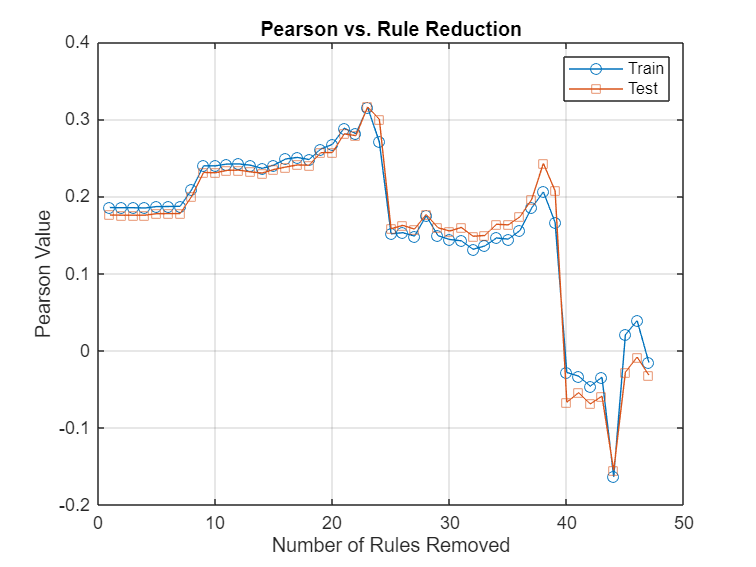

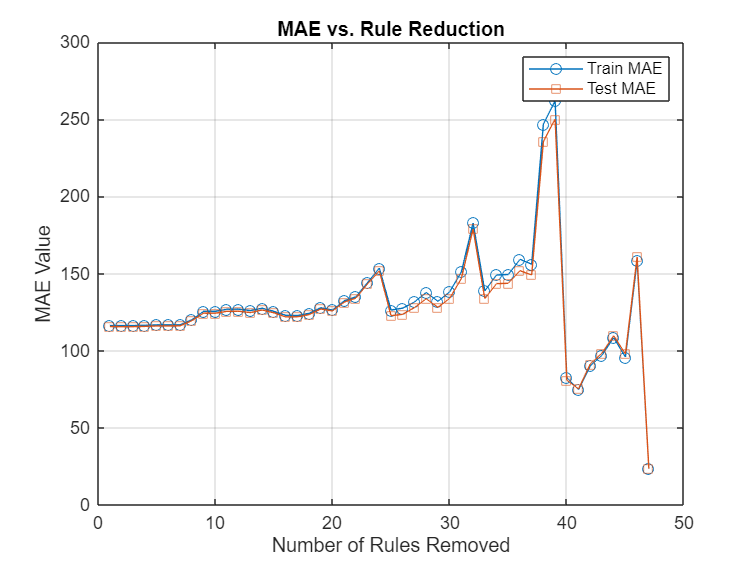

% Visualize performance metrics as rules are progressively removed
visualizeRulesReduction(r2_train, r2_test, mae_train, mae_test, length(r2_train));

%% WEIGHTED ACTIVATION METHOD
% Run weighted activation method to analyze rule usage with weights
ruleUsageCounterWeighted = runWeightedActivationMethod(outputFIS, currentCombination, complete_train_table);

Rule Usage Frequency Analysis:
Rule 1: 2.19% (Activation Count: 9.962849e+01)
Rule 2: 3.98% (Activation Count: 1.809759e+02)
Rule 3: 2.30% (Activation Count: 1.048388e+02)
Rule 4: 4.49% (Activation Count: 2.041902e+02)
Rule 5: 6.30% (Activation Count: 2.867763e+02)
Rule 6: 12.84% (Activation Count: 5.845783e+02)
Rule 7: 6.78% (Activation Count: 3.085425e+02)
Rule 8: 13.62% (Activation Count: 6.199793e+02)
Rule 9: 9.12% (Activation Count: 4.150935e+02)
Rule 10: 17.37% (Activation Count: 7.905480e+02)
Rule 11: 9.12% (Activation Count: 4.149387e+02)
Rule 12: 15.39% (Activation Count: 7.005114e+02)
Rule 13: 10.94% (Activation Count: 4.977949e+02)
Rule 14: 18.17% (Activation Count: 8.271709e+02)
Rule 15: 9.98% (Activation Count: 4.540756e+02)
Rule 16: 15.33% (Activation Count: 6.977384e+02)
Rule 17: 12.09% (Activation Count: 5.502831e+02)
Rule 18: 15.23% (Activation Count: 6.931887e+02)
Rule 19: 9.61% (Activation Count: 4.374906e+02)
Rule 20: 11.64% (Activation Count: 5.300525e+02)
Rule 21:

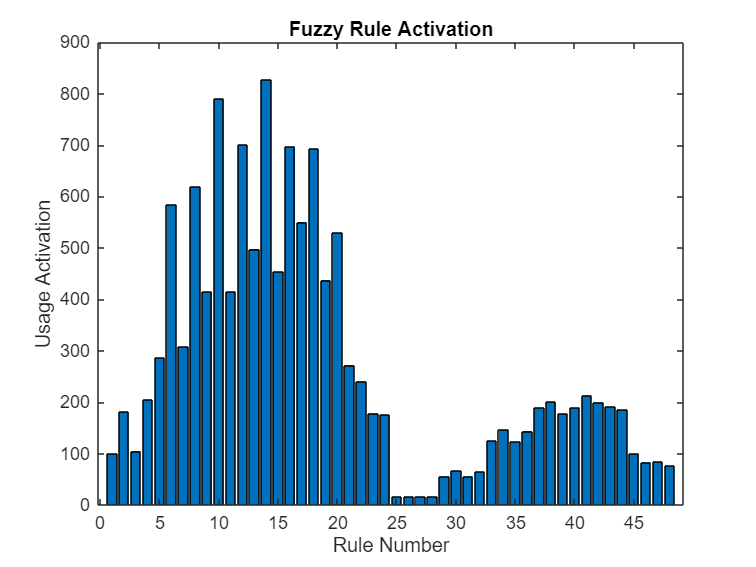

    14    10    12    16    18     8     6    17    20    13    15    19     9    11     7     5    21    22    41     4    38    42    43    40    37    44     2    23    39    24    34    36    33    35     3    45     1    47    46    48    30    32    31    29    28    26    27    25



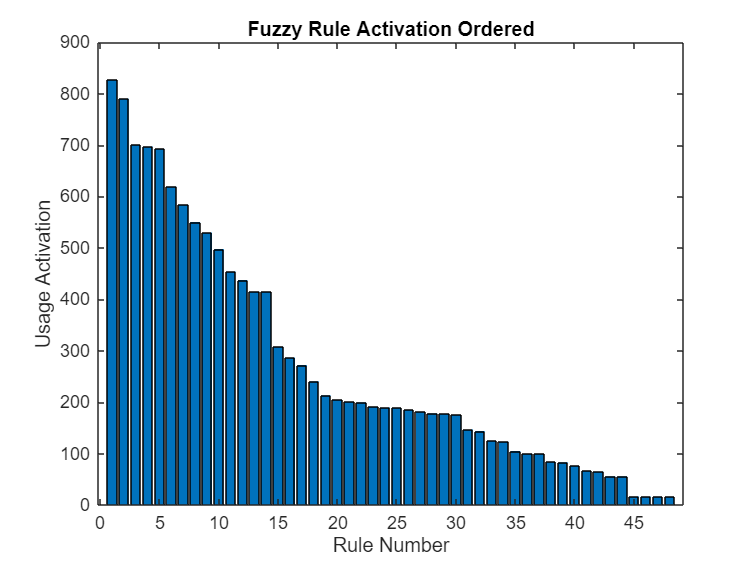

% Visualize rule usage results from weighted activation
visualizeResults(ruleUsageCounterWeighted);

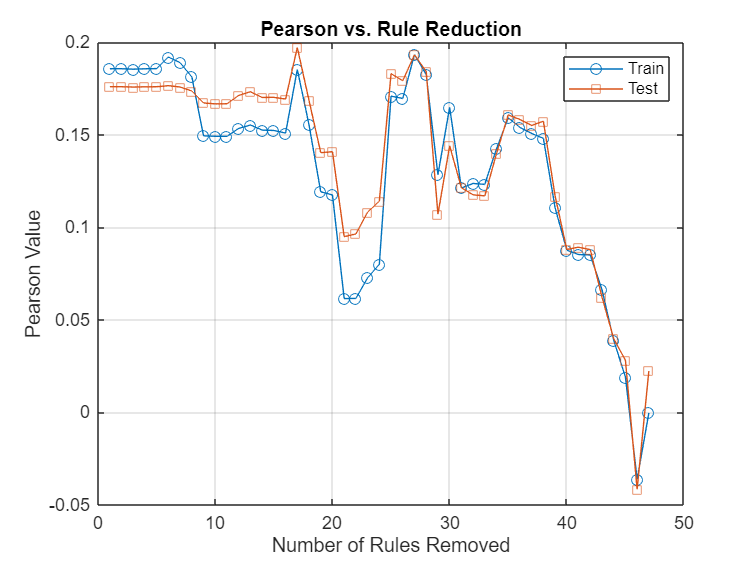

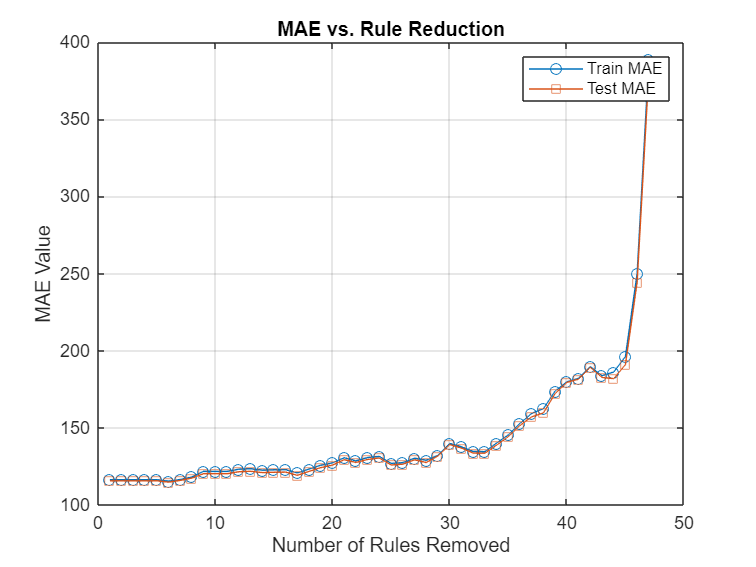


% Evaluate model performance when reducing rules based on weighted activation
[r2_train, r2_test, mae_train, mae_test] = evaluateRulesReduction(outputFIS, ruleUsageCounterWeighted, complete_train_table, complete_test_table, currentCombination, false);

% Visualize performance metrics as rules are progressively removed
visualizeRulesReduction(r2_train, r2_test, mae_train, mae_test, length(r2_train));

%% RULES REDUCTION WITH HYPERPARAMETER TUNING
% Evaluate rules reduction with tuning to find optimal balance between accuracy and rule count
[r2_train, r2_test, mae_train, mae_test] = evaluateRulesReductionWithTuning(outputFIS, ruleUsageCounterWeighted, complete_train_table, complete_test_table, currentCombination, false);

Retraining...

ANFIS info:
	Number of nodes: 127
	Number of linear parameters: 240
	Number of nonlinear parameters: 36
	Total number of parameters: 276
	Number of training data pairs: 4552
	Number of checking data pairs: 0
	Number of fuzzy rules: 48


Start training ANFIS ...

1 	 2.6114
2 	 2.61378
3 	 2.61172
4 	 2.61345
Step size decreases to 0.009000 after epoch 5.
5 	 2.61159
6 	 2.61304
7 	 2.61145
8 	 2.61263
Step size decreases to 0.008100 after epoch 9.
9 	 2.61161
10 	 2.61214

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 2.6114
Retraining...

ANFIS info:
	Number of nodes: 125
	Number of linear parameters: 235
	Number of nonlinear parameters: 36
	Total number of parameters: 271
	Number of training data pairs: 4552
	Number of checking data pairs: 0
	Number of fuzzy rules: 47


Start training ANFIS ...

1 	 2.61163
2 	 2.61402
3 	 2.61194
4 	 2.61369
Step size decreases to 0.009000 after epoch 5.
5 	 2.61182
6 	 2.61324
7 	 2.6

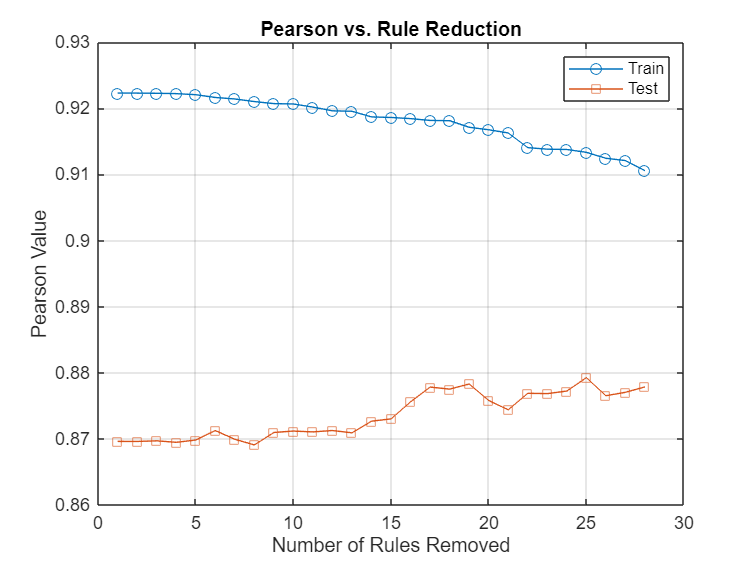

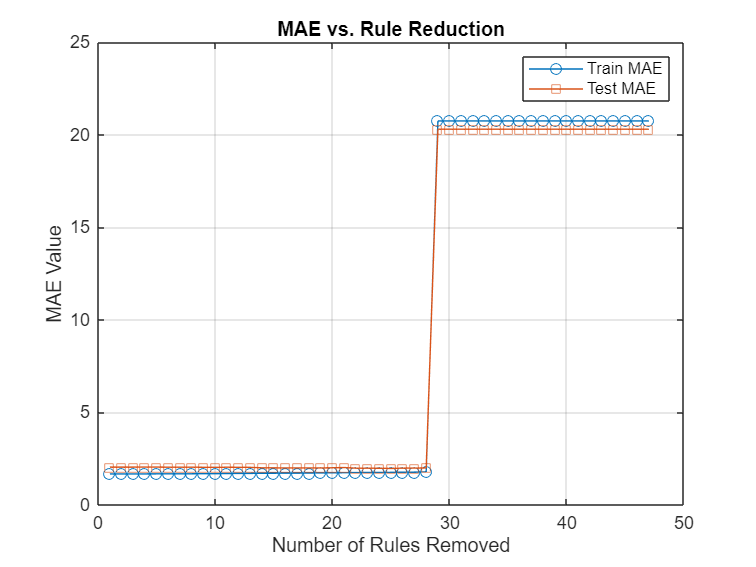


% Visualize full range of reduction results with all rules
visualizeRulesReduction(r2_train, r2_test, mae_train, mae_test, length(r2_train));

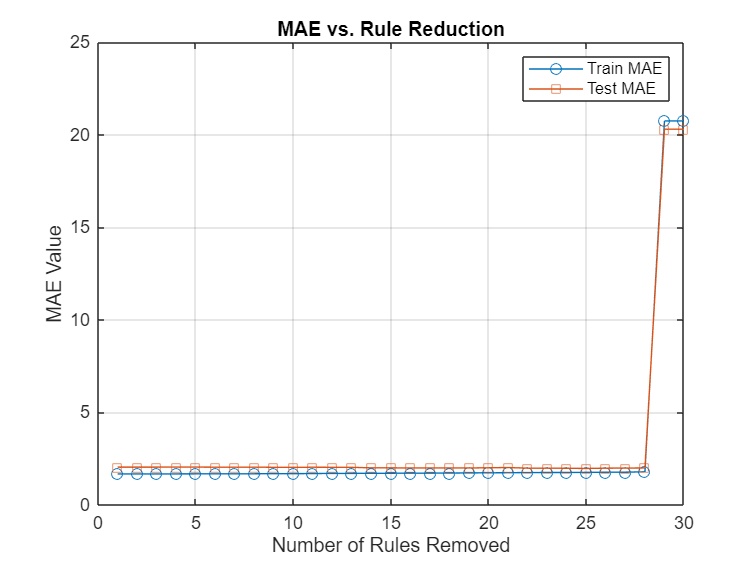


% Visualize reduction results limited to first 30 rule configurations
visualizeRulesReduction(r2_train, r2_test, mae_train, mae_test, 30);

%% EVALUATION WITH SPECIFIC RULE COUNT
% Define the target number of rules before reduction
rules_before_drop = 29;

% Evaluate model performance with a specific number of rules
evaluateRulesReductionWithSpecificNumberOfRules(outputFIS, ruleUsageCounterWeighted, complete_train_table, complete_test_table, currentCombination, true, rules_before_drop)

    48

    29

Retraining...

ANFIS info:
	Number of nodes: 89
	Number of linear parameters: 145
	Number of nonlinear parameters: 36
	Total number of parameters: 181
	Number of training data pairs: 4552
	Number of checking data pairs: 0
	Number of fuzzy rules: 29


Start training ANFIS ...

1 	 2.73191
2 	 2.72903
3 	 2.72634
4 	 2.72354
Step size increases to 0.011000 after epoch 5.
5 	 2.71987
6 	 2.71451
7 	 2.70722
8 	 2.70369
Step size increases to 0.012100 after epoch 9.
9 	 2.70077
10 	 2.69933

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 2.69933
    SensorID      R2        MAE       MSE       RMSE 
    ________    _______    ______    ______    ______

    "-2433"      0.9118    1.7168    7.0742    2.6597
    "-2432"     0.92245    1.7619    7.5767    2.7526


ans = 0.9168